## Project 2: Calculating Values at Risk

### 1.

Let the log returns $X$ be given by $X_t =\log \left(V_t \right)-\log \left(V_{t-1} \right)$. Let $F_{X_t } =P\left(X_t \le \cdot \left|\left(X_s ,V_s ,s<t\right)\right.\right)$ be the cumulative distribution function of $X_t$ given all information up to time $t-1$. Show that


$${\textrm{VaR}}_t =V_{t-1} \left(e^{F_{X_t }^{-1} \left(p\right)} -1\right)$$



$$p=P\left(V_t -V_{t-1} \le {\textrm{VaR}}_t \;\left|\;\left(V_s ,s<t\right)\right.\right)$$



$$F_{X_t }^{-1} \left(p\right)=\left\lbrace x:P\left(X_t \le x\;\left|\;\left(X_s ,V_s ,s<t\right)\right.\right)=p\right\rbrace$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left\lbrace x:P\left(X_t \le x\;\left|\;\left(X_s ,V_s ,s<t\right)\right.\right)=P\left(V_t -V_{t-1} \le {\mathrm{VaR}}_t \;\left|\;\left(V_s ,s<t\right.\right.\right)\right\rbrace$$


Above, $\left\lbrace x:y\right\rbrace$is read as "$x$ such that $y$ holds"


$$\begin{array}{l}
X_t =\mathrm{log}\left(V_t \right)-\mathrm{log}\left(V_{t-1} \right)\\
\;\;\;\;=\mathrm{log}\left(\frac{V_t }{V_{t-1} }\right)\\
e^{X_t } =\frac{V_t }{V_{t-1} }\\
V_{t-1} \left(e^{X_t } -1\right)=V_t -V_{t-1} 
\end{array}$$



$$\begin{array}{l}
P\left(V_t -V_{t-1} \le {\mathrm{VaR}}_t \;|\;\left(V_s ,s<t\right)\right)=P\left(V_{t-1} \left(e^{X_t } -1\right)\le {\mathrm{VaR}}_t \;\left|\;\left(V_s ,s<t\right)\right.\right)=P\left(e^{X_t } \le \frac{{\mathrm{VaR}}_t }{V_{t-1} }+1\left|\;\left(V_s ,s<t\right)\right.\right)\\
=P\left(X_t \le \mathrm{log}\left(\frac{{\mathrm{VaR}}_t }{V_{t-1} }+1\right)\left|\;\left(V_s ,s<t\right)\right.\right)
\end{array}$$



$$\begin{array}{l}
F_{X_t }^{-1} \left(p\right)=\left\lbrace x:P\left(X_t \le x\;\left|\;\left(X_s ,V_s ,s<t\right)\right.\right)=P\left(X_t \le \log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)\left|\;\left(V_s ,s<t\right)\right.\right)\right\rbrace \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left\lbrace x:x=\log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)\right\rbrace =\log \left(\frac{{\textrm{VaR}}_t }{V_{t-1} }+1\right)
\end{array}$$



$$\begin{array}{l}
F_{X_t }^{-1} \left(p\right)=\mathrm{log}\left(\frac{{\mathrm{VaR}}_t }{V_{t-1} }+1\right)\\
e^{F_{X_t }^{-1} \left(p\right)} =\frac{{\mathrm{VaR}}_t }{V_{t-1} }+1\\
{\mathrm{VaR}}_t =V_{t-1} \left(e^{F_{X_t }^{-1} \left(p\right)} -1\right)
\end{array}$$


### 2.

Plot the (sample) autocorrelation and partial autocorrelation functions of X for lags h = 0,...,50

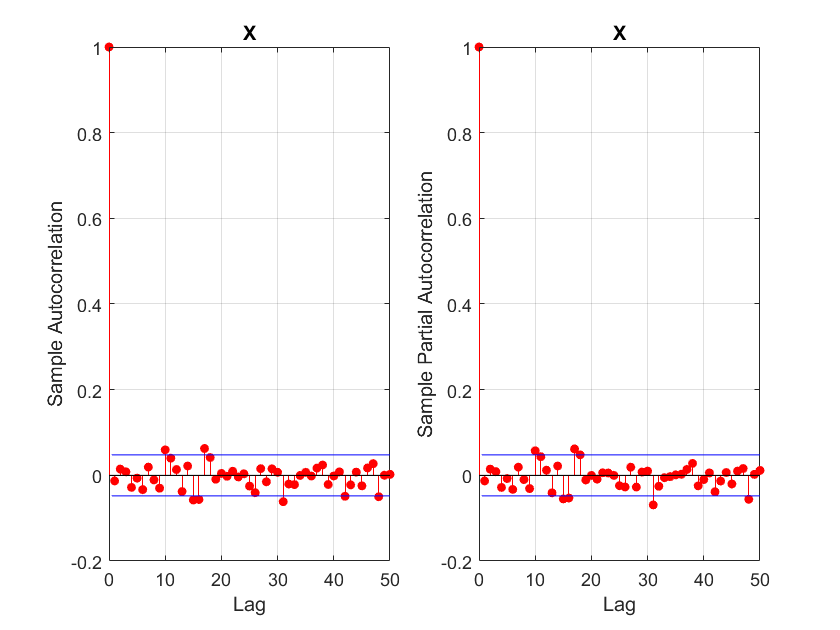

V = readtable('dat_intel.csv');
X = log(V.Close(2:end)) - log(V.Close(1:end-1));

subplot(1,2,1)
autocorr(X,'NumLags',50)
title('X')
ylim([-.2, 1])
xlim([0, 50])

subplot(1,2,2)
parcorr(X,'NumLags',50)
title('X')
ylim([-.2, 1])
xlim([0, 50])

Then, do a Ljung–Box test with h = 50 for X

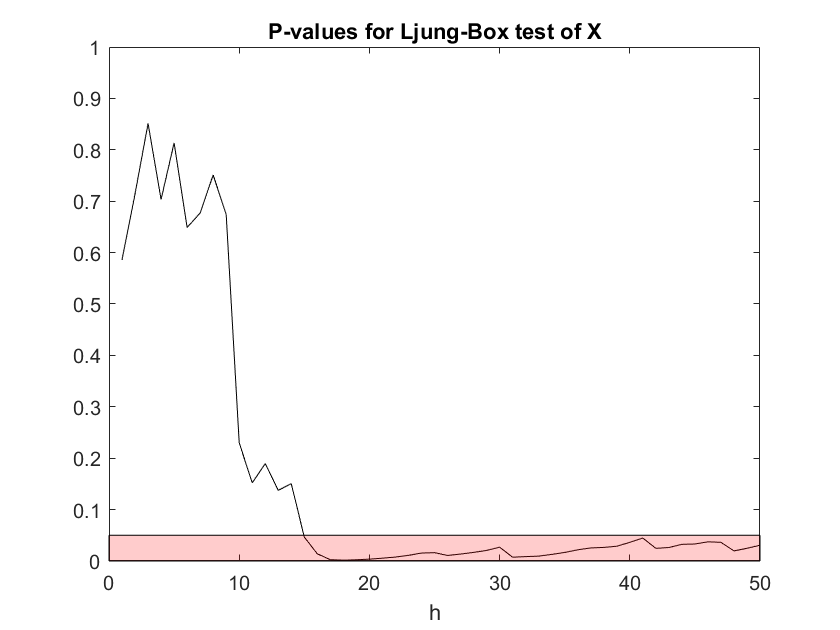

alpha = .05;
lags = 1:50;

[h, pValues, stat, cValue] = lbqtest(X, 'lags', lags);

p = plot(lags, pValues, 'k');
tmp_x = [p.Parent.XLim(1) p.Parent.XLim(1) p.Parent.XLim(2) p.Parent.XLim(2)];
tmp_y = [p.Parent.YLim(1) alpha alpha p.Parent.YLim(1)];
patch(tmp_x, tmp_y, 'r', 'facealpha', .2)
ylim([0, 1])
title('P-values for Ljung-Box test of X')
xlabel('h')

if pValues(find(lags==50)) < alpha
    disp('Reject H0 at h=50')
else
    disp('Fail to reject H0 at h=50')
end

Reject H0 at h=50


Repeat these two steps with the squared returns $X^2$. We start with the (sample) autocorrelation and partial autocorrelation functions of $X^2$ for lags h = 0,...,50

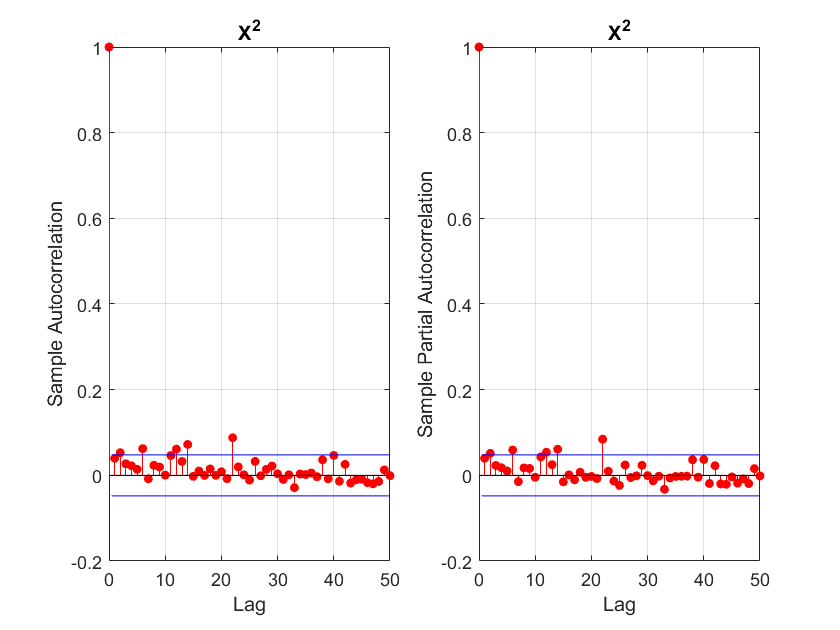

subplot(1,2,1)
autocorr(X.^2,'NumLags',50)
title('X^2')
ylim([-.2, 1])
xlim([0, 50])
subplot(1,2,2)
parcorr(X.^2,'NumLags',50)
title('X^2')
ylim([-.2, 1])
xlim([0, 50])

do a Ljung–Box test with h = 50 for X^2

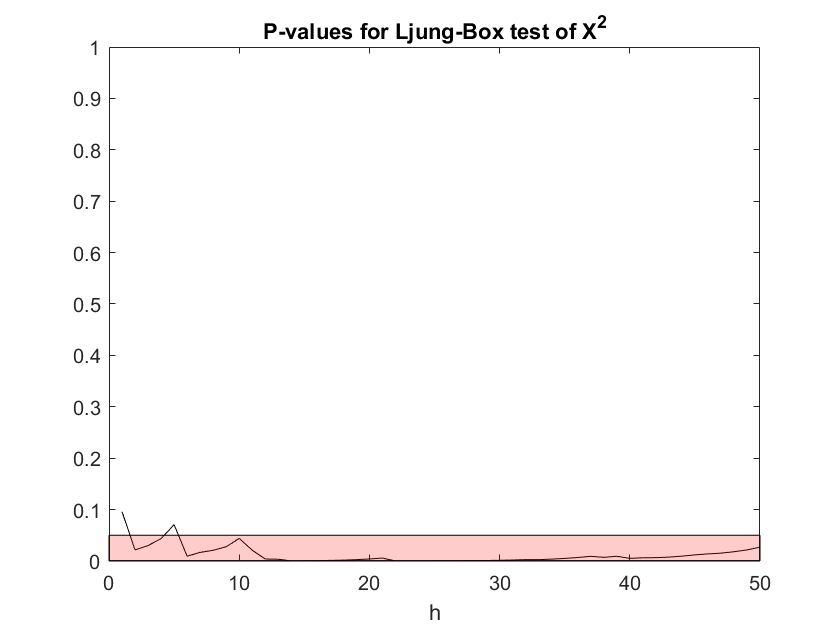

[h, pValues, stat, cValue] = lbqtest(X.^2, 'lags', lags, 'Alpha', alpha);

p = plot(lags, pValues, 'k');
tmp_x = [p.Parent.XLim(1) p.Parent.XLim(1) p.Parent.XLim(2) p.Parent.XLim(2)];
tmp_y = [p.Parent.YLim(1) alpha alpha p.Parent.YLim(1)];

patch(tmp_x, tmp_y, 'r', 'facealpha', .2)
ylim([0, 1])
title('P-values for Ljung-Box test of X^2')
xlabel('h')

if pValues(find(lags==50)) < alpha
    disp('Reject H0 at h=50')
else
    disp('Fail to reject H0 at h=50')
end

Reject H0 at h=50


#### Discussion

Both $X$ and $X^2$ (the squared returns) have outliers on the autocorrelation function plots. They are not very large, but significant enough to be above the 95% confidence interval plotted at several lags, indicating that the series is not entirely white noise. For both $X$ and $X^2$ we reject the Ljung-Box null hypotheses that $X$ and $X^2$ are realizations of $\mathrm{IID}\left(\mu \;,\sigma {\;}^2 \right)$ at the 5% level for $h=50$. 

### 3)

Now split the time series $X$ into a training set ($X_t$ , t = 2,...,1526) and a test set ($X_t$ , t = 1527, . . . , 1751).

trainX = X(2:1526);
testX = X(1527:1750);

#### Gaussian distribution

For all values of p and q in the range 0, 1, . . . , 15 and such that p+q > 0 and p ≥ q, fit an ARMA(p, q) process with Gaussian noise to the square returns obtained from the training data and compute the BIC and the AICC (this will take a couple of minutes). Which models minimize the two information criteria? 

i=1;
for p = 0:15
    for q = 0:p
        if p+q>0 && p>=q
            mdl(i) = arima(p,0,q); 
            i = i + 1;
        end
    end
end

https://se.mathworks.com/help/econ/aicbic.html

for i = 1:size(mdl,2)
    [EstMdl,~,logL(i)] = estimate(mdl(i),X.^2,'Display','off');
    results = summarize(EstMdl);
    numParam(i) = results.NumEstimatedParameters;
end

Note! ic part did not work when using R2020a. Tested and work on R2021a.

[aic,bic,ic] = aicbic(logL,numParam);
[~,minIdx] = structfun(@min,ic);
minIdxChosen = [minIdx(2:3)];
[mdl(minIdxChosen).Description]'
bestmdlGaussian = mdl(minIdx(2));

According to hints and notes: 

*•Compute the BIC and AICC using the formulas given in Methods 3.2.22 and 3.2.23 of the lecture notes. Think of replacing the quantity p + q + 1 by the number M of (non-zero) parameters actually estimated by the algorithm. *

So using aicbic might not be the way they want us to get it. This could maybe be used if our own formulas is correct or not.

#### Student’s *t distribution*

i=1;
for p = 1:15
    for q = 0:p
        mdl(i) = arima(p,0,q); 
        mdl(i).Distribution="t";
        i = i + 1;
    end
end

for i = 1:size(mdl,2)
    try
        [EstMdl,~,logL(i)] = estimate(mdl(i),X.^2,'Display','off');
        results = summarize(EstMdl);
        numParam(i) = results.NumEstimatedParameters;
    catch
        disp("error")
        disp(mdl(i).Description)
        disp("")
    end
end

[aic,bic,ic] = aicbic(logL,numParam);
[~,minIdx] = structfun(@min,ic);
minIdxChosen = [minIdx(2:3)];
[mdl(minIdxChosen).Description]'
bestmdlT = mdl(minIdx(2));

EstMdlG = estimate(bestmdlGaussian,X.^2)

[resG, v] = infer(EstMdlG, X.^2);
sresG = resG./sqrt(v);
autocorr(sresG,'NumLags',50)

lags = 1:50;
[h, pValues, stat, cValue] = lbqtest(sresG, 'lags', lags);
p = plot(lags, pValues, 'k');
ylim([0, 1.1])
title('p-values for LGQ-test')

EstMdlT = estimate(bestmdlT,X.^2)

[resT, v] = infer(EstMdlT, X.^2);
sresT = resT./sqrt(v);
autocorr(sresT,'NumLags',50)

[h, pValues, stat, cValue] = lbqtest(sresT, 'lags', lags);

Unrecognized function or variable 'sresT'.

p = plot(lags, pValues, 'k');
ylim([0, 1.1])
title('p-values for LGQ-test')
